clear all;
clc;

## Parameters:

% L = 0.076;
% dsl = 0.5;
% dso = -0.5;
% no_st_turns= 600*2;
% no_rt_turns = 1;
% r = 73.75e-3;
% g0 = 0.5e-3;

L = 130e-3;
% dsl =0.5 ;
% dso = 0;
no_st_turns= 4;
no_rt_turns =20;
r = 0.0634;
% r = 0.0642;
g0 = 1.6*1e-3;
% i_z = 1;

%  L = 110e-3;
% dsl = 0.3;
% dso = 0.0;
% no_st_turns=67;
% no_rt_turns = 1;
% r = 75e-3;
% g0 = 0.45e-3;

 % dt = 0.0163;
 dt = 0.025;
 % dt = 0.001;
tend = 1;
t= 0:dt:tend;
[~, size_t] =size(t);

phi_size = 500;
k =11;
h_size = 200;

phi = linspace(0, 2*pi, phi_size);
z = linspace(0, L, k);
    % z = 0:0.013:0.13;
 % z = 0.001:0.0116:0.129;
 % z = 0:0.013:0.0520;
mu_0 = 4* pi* 10^(-7);

theta_inductance = linspace(0, 2*pi, size_t);

f=60;
TL = 4.2;
Rs = 0.1535;
Rr = 0.08175;
Lls = 0.211e-3;
Llr = 0.211e-3;
P = 4;
B=0;
J=0.0889;

% Rs = 0.0415;
% Rr = 0.0204;
% Lls = 0.0527e-3;
% Llr =0.048e-3 ;
% P = 4;
% B=0;
% J=0.0889;

% J=0.0244;
Vm = 29.39;
N = 1;

## Initialization of matrices:

Labcsr =  zeros(3,3,size_t);
Labcrs =  zeros(3,3,size_t);

Lxy_for_theta = zeros( size_t, 6,  6);
Lxy_mat = zeros(6, 6, size_t, k);

Lxy_mat_diff = zeros(6, 6, size_t, k);
Lxy_for_theta_diff = zeros( size_t, 6,  6);

dz = L / k;

G_for_z = zeros(phi_size, k);
turns_phases = cell(2, 3);
winding_phases = cell(2, 3);
G_max = zeros(1, length(z));

for phase = 1:3
    turns_phases{1, phase} = zeros(1, phi_size);
    turns_phases{2, phase} = zeros(size_t, phi_size);
    winding_phases{1, phase} = zeros(phi_size, k);
    winding_phases{2, phase} = zeros(size_t, phi_size);
end

## Resistances:

R1 = [Rs 0 0; 0 Rs 0; 0 0 Rs];
R2 = [Rr 0 0; 0 Rr 0; 0 0 Rr];

## Current Calculation:

% Calculate stator Turns
% Stator Turns function is calculated for every phase
% This does not depened on theta or z so we calculate it outside the loops.
for phase = 1:3
    turns_phases{1, phase} = stator_turns(phi, h_size, phase, no_st_turns);
end


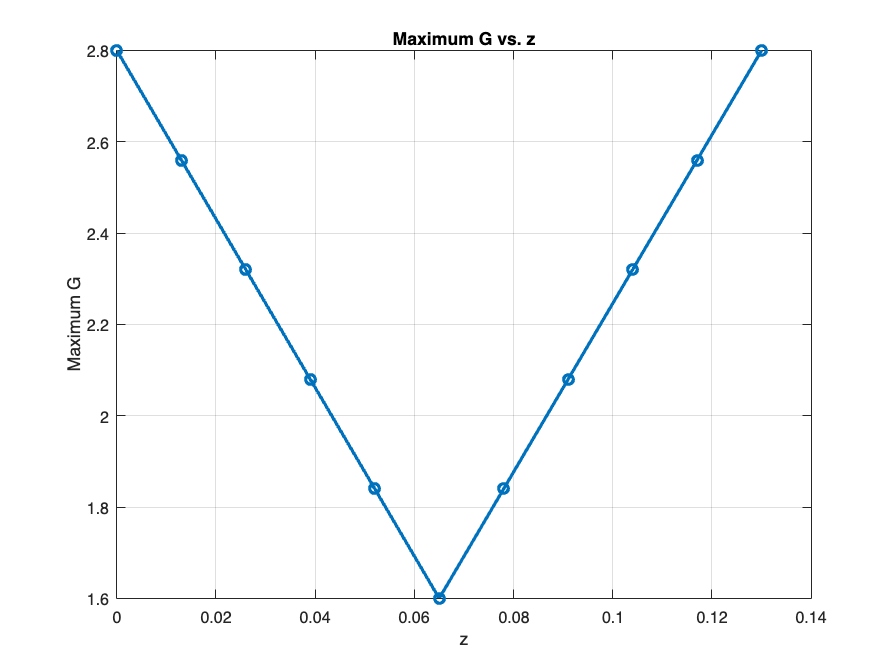


% % Calculate inductances for each angle
for t_i = 1:size_t
%     
%     % Rotor turns function
%     for phase = 1:3
%         turns_phases{2, phase}(t_i, :) = rotor_turns(phi, theta_inductance(t_i), no_rt_turns, phase, h_size);
%          % turns_phases{2, phase}(t_i, :) = rotor_turns(phi, 0, no_rt_turns, phase, h_size);
%     end
% 
%     %Initialize arrays for EACH PHASE
%     [s_w_temp, r_w_temp, L_yx_temp, int_n_over_g_sum_s, g_avg_sum_s, int_n_over_g_sum_r, g_avg_sum_r] = initialize_arrays();
% 
% 
     for i_z = 1: k
%           % Calculate Air Gap function
            % d_z = (((dsl-dso)/L)*z(i_z))+(dso);
            %  G = g0 * (1 - ((d_z.* cos(phi))));
             dsl = 1.2;
             dso = -1.2;
             gs = (1.6+dsl)*1e-3;
             gl = (1.6+dso)*1e-3;
             delg = gs-gl;
             d_z = -(gs-g0)+(z(i_z)*delg)/L;
             G =  g0-((((0.* cos(phi)))));

             % d_z = -0.001+ (z(i_z)/130);
             %  G =  g0-((((d_z.* cos(phi)))));

             % d_z = ((((-0.001)+(z(i_z)/65))));
             %  % % d_z = (1.625+(dz*i_z/-65))*0.001;
              % G =  g0-((((d_z.* cos(phi)))));
              % G(i_z,250)

             % d_z = -0.001+(z(i_z)/65);
            % G = g0 - d_z.*cos(phi);
           G_for_z(:, i_z)= G;
           G_max(i_z) = max(G)*1e3;
%         % Calculate Winding function for each phase, for stator and rotor
%         for phase = 1:3
%             [s_w_temp(phase), int_n_over_g_sum_s(phase), g_avg_sum_s(phase)] = winding_function(turns_phases{1, phase}, G, phi, dz, L, g_avg_sum_s(phase), int_n_over_g_sum_s(phase), r);
%             winding_phases{1, phase}(:, i_z) = (turns_phases{1, phase} - s_w_temp(phase));
%             [r_w_temp(phase), int_n_over_g_sum_r(phase), g_avg_sum_r(phase)] = winding_function(turns_phases{2, phase}(t_i, :), G, phi, dz, L, g_avg_sum_r(phase), int_n_over_g_sum_r(phase), r);
%             winding_phases{2, phase}(t_i, :) = turns_phases{2, phase}(t_i, :) - r_w_temp(phase);
%         end
%         % integrand = turns_phases{1, 1}.*winding_phases{1,1 }(:, i_z)'./ (G);
%         % % integrand = (winding_phases{1,1}(:, i_z).* winding_phases{1,2}(:, i_z))'./ (G);
%         % Lxy_mat(1, 1, t_i, i_z) = (dz*mu_0 * r).* trapz(phi, integrand);
%         % Lxy_for_theta(t_i,1, 1) = Lxy_mat(1, 1, t_i, i_z) + Lxy_for_theta(t_i, 1, 1);
%         % for i = 1:6
%         %     for j = 1:6
%         %         [turns_phase_selected, winding_phase_selected] = select_phases(i-1, j-1, t_i, i_z, turns_phases, winding_phases);
%         %         integrand = turns_phase_selected.*winding_phase_selected./ (G);
%         %         Lxy_mat(i, j, t_i, i_z) = (dz*mu_0 * r).* trapz(phi, integrand);
%         %         % Lxy_mat(i, j, t_i, i_z) = (dz*mu_0 * r).*  integrand;
%         %         Lxy_for_theta(t_i,i, j) = Lxy_mat(i, j, t_i, i_z) + Lxy_for_theta(t_i, i, j);
%         %     end
%         % end
% 
    end
end

figure;
plot(z, G_max, '-o', 'LineWidth', 2);
xlabel('z');
ylabel('Maximum G');
title('Maximum G vs. z');
grid on;

% for t_i = 1:size_t
%     Lxy_for_theta(t_i, 1:3, 4:6)= ((Lxy_for_theta(t_i, 1:3, 4:6)))*(0.28);
%     Lxy_for_theta(t_i, 4:6, 1:3) = ((Lxy_for_theta(t_i, 4:6, 1:3)))*(0.28);
%     Lxy_for_theta(t_i, 4:6, 4:6) = ((Lxy_for_theta(t_i, 4:6, 4:6))*((0.28)^2));
% end


% for i = 1:6
%     for j = 1:6   
% %         % Computing differentiation for all elements
% %         % Normalizing the differentiated values to match the amplitude of Lxy_for_theta(:, 5)
% %        max_amplitude = max(abs(Lxy_for_theta(:, i, j)));
% %       normalized_diff = (Lxy_for_theta(:, i, j) / max(abs(Lxy_for_theta(:, i, j)))) * max_amplitude;
%        Lxy_for_theta_diff(:, i, j) = gradient(squeeze(Lxy_for_theta(:, i, j)))./(gradient(theta_inductance)');
%         % Lxy_for_theta_diff(1:(size_t -1), i, j) = diff(squeeze(Lxy_for_theta(:, i, j)))./(diff(theta_inductance))';
%     end
% end



% dt_curr =0.0001;
% tend_curr = 5;
% curr_t = 0:dt_curr:tend_curr;
% [~, curr_size_t] =size(curr_t);
% phis  = zeros(3,1,curr_size_t);
% phir = zeros(3,1,curr_size_t);
% Ir = zeros(3,1, curr_size_t);
% Is = zeros(3,1, curr_size_t);
% Te = zeros(1,curr_size_t);
% Va = zeros(1,curr_size_t);
% Vb = zeros(1,curr_size_t);
% Vc = zeros(1,curr_size_t);
% Vs = zeros(3,1,curr_size_t);
% theta = zeros(1,curr_size_t);
% omega = zeros(1,curr_size_t);
% % Labcs_values = zeros(3, 3, size_t);
% % Labcr_values = zeros(3, 3, size_t);
% % Lls = 0.27527e-3;
% % Llr = 0.27527e-3;
% %  Lm = 3.6514e-3;
% % Lms =(2/3)*Lm;
% % Lmr = Lms;
% % Lsr = Lmr;
% % for i = 1:size_t
% %    Labcs = [Lls+Lms, -0.5*Lms, -0.5*Lms; -0.5*Lms, Lls+Lms, -0.5*Lms; -0.5*Lms, -0.5*Lms, Lls+Lms];
% %    Labcr = [Llr+Lmr, -0.5*Lmr, -0.5*Lmr; -0.5*Lmr, Llr+Lmr, -0.5*Lmr; -0.5*Lmr, -0.5*Lmr, Llr+Lmr];
% % % end
% for t_i = 1:curr_size_t
%     %12. Calculate Voltges
%     Vb(t_i) = Vm*sin(2*pi*f*curr_t(t_i)-(120*pi/180));
%     Vc(t_i) = Vm*sin(2*pi*f*curr_t(t_i)+(120*pi/180));
%     Va(t_i) = Vm*sin(2*pi*f*curr_t(t_i)); 
%     Vs(:, :, t_i) = [Va(t_i);Vb(t_i);Vc(t_i)];
% 
%     if t_i > 1
% 
%         theta_mod = mod(theta(t_i-1)*(2/P), 2*pi);
%         [~, idx] = min(abs(theta_inductance - theta_mod));
% 
%         Labcs = squeeze(Lxy_for_theta(idx, 1:3, 1:3))+(Lls*eye(3));
%         Labcsr = (squeeze(Lxy_for_theta(idx, 1:3, 4:6)));
%         Labcrs = (squeeze(Lxy_for_theta(idx, 4:6, 1:3)));
%          Labcr = (squeeze(Lxy_for_theta(idx, 4:6, 4:6)))+(Llr*eye(3));
% 
%         % Labcs = Labcs_values(:,:,idx);
%         % Labcr = Labcr_values(:,:,idx);
%         % Labcrs_prev = Labcr;
% 
%         Labcsrdiff = (squeeze(Lxy_for_theta_diff(idx, 1:3, 4:6)));
%         Labcrsdiff = (squeeze(Lxy_for_theta_diff(idx, 4:6, 1:3)));
%         Labcrdiff = (squeeze(Lxy_for_theta_diff(idx, 4:6, 4:6)));
% 
%         % 6. Calculate current vectors [Is]t_i-1 and [Ir]t_i-1 using (23) and (24)
%         Ir(:, : , t_i-1)= ((inv(Labcr-((Labcsr)'*inv(Labcs)*Labcsr)))*(N*phir(:,:,t_i-1) - ((Labcsr)'*inv(Labcs)*phis(:,:,t_i-1))));
%         Is(:, :, t_i-1) = (inv(Labcs)*phis(:,:,t_i-1))-(inv(Labcs)*Labcsr*Ir(:,:,t_i-1));
% 
%         % 7. Calculate induced torque Te,t_i-1
%         Te(t_i-1) = (P/2)*(((((0.5*(Is(:,:,t_i-1))'* Labcsrdiff*(Ir(:,:,t_i-1)))+(0.5*(Ir(:,:,t_i-1))'* Labcrsdiff*(Is(:,:,t_i-1))))) + (0.5* (Ir(:, :, t_i-1))'*Labcrdiff*(Ir(:, :, t_i -1)))));
%          % Te(t_i-1) = (P/2)*((((0.5*(Is(:,:,t_i-1))'* Labcsrdiff*(Ir(:,:,t_i-1)))+(0.5*(Ir(:,:,t_i-1))'* Labcrsdiff*(Is(:,:,t_i-1))))));
%         % Te(t_i-1) = (((0.5*(Is(:,:,t_i-1))'* Labcsrdiff*(Ir(:,:,t_i-1)))+(0.5*(Ir(:,:,t_i-1))'* Labcrsdiff*(Is(:,:,t_i-1)))));
% 
%         % 8. Calculate flux linkage vectors [ψs]t_i and [ψr]t_i using (21) and (22)
%         phis(:,:,t_i) = ((Vs(:, :, t_i-1)-(R1*Is(:,:,t_i-1))))*dt_curr + phis(:,:,t_i-1);
%         phir(:,:,t_i)= (-(R2*Ir(:,:,t_i-1))*dt_curr*(1/N)) + phir(:,:,t_i-1);
% 
%         % 9. Calculate rotor angular speed ωi and position θi using (25) and 26
%         omega(t_i) = ((((((1/(J))*(Te(t_i-1)- TL)))*dt_curr*(P/2))) + omega(t_i-1));
%         theta(t_i) = ((omega(t_i)*dt_curr)+ theta(t_i-1));
%     end
% end

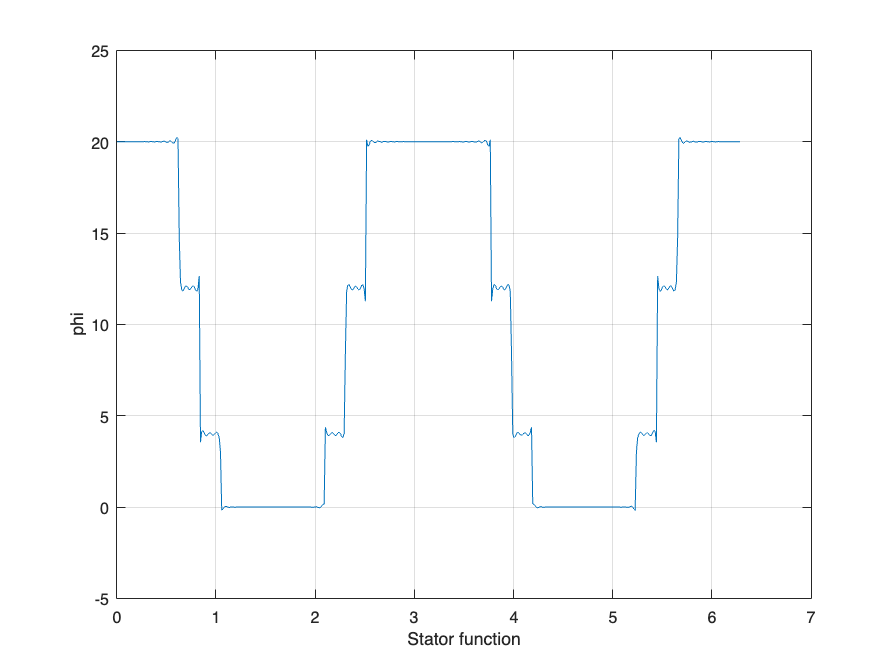

% % Initialize the Figure
% figure;
% data = squeeze(Lxy_mat(4, 4, :, :)*1e3);
% % Plot the First Surface (Blue)
 [Z, Phi] = meshgrid(z, phi);
%  % [Z, Phi] = meshgrid(z, phi);
% Phi = Phi *180/ pi;
% area = size_t;
%  s1 = surf(Phi(1:area,:), Z(1:area,:), squeeze(Lxy_mat(4, 4, 1:area, :)*1e3));
% % surf(Phi, Z, squeeze(Lxy_mat(4, 4, :, :)*1e3));
% s1.FaceColor = 'b'; % Set color to blue
% s1.FaceAlpha = 0.5;
% % 
%  % hold on;
% 
% % Load Data and Plot the Second Surface (Green)
% [filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; '*.*', 'All Files (*.*)'}, 'Select an Excel file');
% fullpath = fullfile(pathname, filename);
% data = readcell(fullpath);
% x = cell2mat(data(1:41, 1));
% y = cell2mat(data(1:41, 2));
% z = cell2mat(data(1:41, 3:13));
% [X, Y] = meshgrid(y, x);
% s2 = surf(Y, X, z);
% s2.FaceColor = 'g'; % Set color to green
% s2.FaceAlpha = 0.5;
% 
% % Finalize the Plot
% xlabel('X-axis');
% ylabel('Y-axis');
% zlabel('Z-axis');
% title('3D Surface Plot');
%  % hold off
% 
%    plot_surf(Phi, Z, squeeze(Lxy_mat(4, 4,:, :)*1e3), 'Phi (radians)', 'Z (meters)', 'Inductance', 'G vs Phi vs Z');

% plot_surf(Phi(4:1001, 4:80), Z(4:1001, 4:80), squeeze(Lxy_mat_diff(4, 1,4:1001, 4:80)), 'Phi (radians)', 'Z (meters)', 'Inductance', 'G vs Phi vs Z');
plot_phi(phi, turns_phases{1, 1}, 'Stator function' ,'phi');

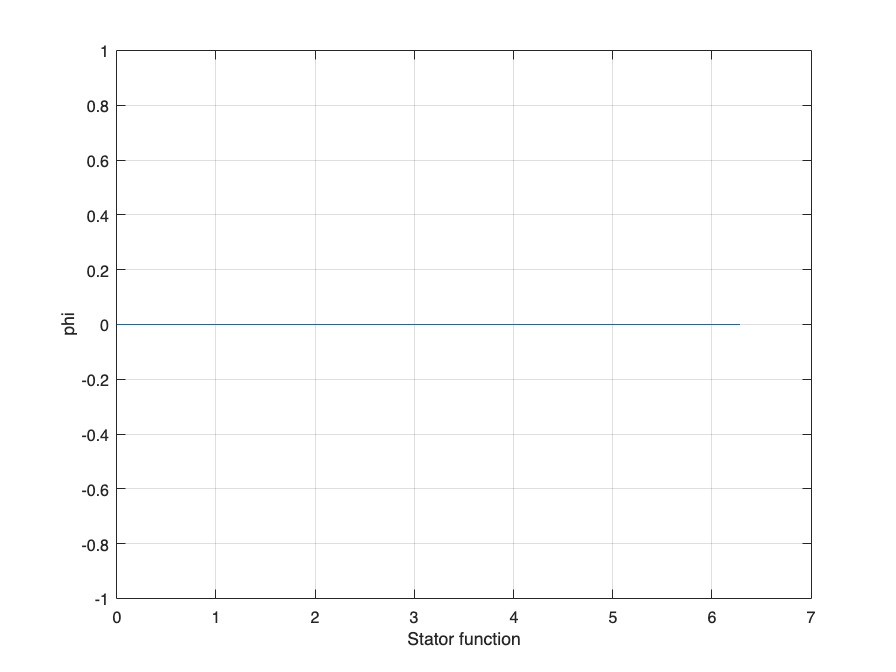

 plot_phi(phi, winding_phases{1, 1}(:, 1), 'Stator function' ,'phi');

 plot_phi(phi, winding_phases{1, 1}(:, 11), 'Stator function' ,'phi');

% plot_surf(Phii(2:101, 2:101), Phi(2:101, 2:101), turns_phases{2, 1}(2:101, 2:101), 'Z (meters)', '\phi (radians)', 'Winding Function', 'L_{yx} vs Z vs \theta');
 % plot_surf(theta_inductance, Phi(:,1), winding_phases{2, 1}(, 'Z (meters)', '\phi (radians)', 'Winding Function', 'L_{yx} vs Z vs \theta');
% plot_phi(theta_inductance, winding_phases{2, 1}(:,), 'Stator function' ,'phi');
plot_surf(Z, Phi, test_winding, 'Z (meters)', '\phi (radians)', 'Winding Function', 'L_{yx} vs Z vs \theta');

Unrecognized function or variable 'test_winding'.

% for i = 1:6
%     for j = 1:6
%         subplot(6,6,(i-1)*6+j) % 5 is used because the maximum iteration of k is 5
%         plot(theta_inductance, squeeze(Lxy_for_theta(:, i,j)));
%         hold on;
%         plot(theta_inductance, squeeze(Lxy_for_theta_diff(:, i,j)));
%         hold off;
%     end
%  end
% calculated_amplitude = (max(squeeze(Lxy_for_theta(:, 1, 4))) - min(squeeze(Lxy_for_theta(:, 1, 4)))) / 2% Simulated stator current data

Plotting healthy:

% save_L = squeeze(Lxy_for_theta(:, 1,1)*1e3);
% theta_inductance_degrees = (theta_inductance*180)/pi;
% color_WFM = [0 0.4470 0.7410];
% plot(theta_inductance_degrees(:,1:501), squeeze(Lxy_for_theta(1:501, 1,4)*1e3),'Color',color_WFM);
% grid on;
% hold on;
% [filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
%                                   '*.*', 'All Files (*.*)'}, ...
%                                   'Select an Excel file');
% fullpath = fullfile(pathname, filename);
% data = readcell(fullpath);
% degrees = cell2mat(data(2:32, 1)); % Convert cell array to a numeric array
% L = cell2mat(data(2:32, 2)); % Convert cell array to a numeric array
% color = [0.8500 0.3250 0.0980];
% plot(degrees, L, 'Color',color);
% hold off;
 % surf(Phi, Z, squeeze(Lxy_mat(4, 4, :, :)*1e3));

plot_phi(theta_inductance, squeeze(Lxy_for_theta(:, 4,4)), 'Stator function' ,'phi');
% hold on
% plot_phi(theta_inductance, squeeze(Lxy_for_theta_diff(:, 1,4)), 'Stator function' ,'phi');
% hold off;

% plot_surf(Phi, Z, G_for_z, 'Phi (radians)', 'Z (meters)', 'Inductance', 'G vs Phi vs Z');



% plot_phi(theta_inductance, squeeze(Lxy_mat(4, 1, :, 1)), 'Stator function' ,'phi');


% plot_surf(Theta, Phi, winding_phases{2, 1}, 'Z (meters)', '\phi (radians)', 'Winding Function', 'L_{yx} vs Z vs \theta');
% Now C is a 3-by-3 matrix with the last column being all zeros
[Z_i, Theta] = meshgrid(z, phi);

## Plot Current:

% Extract the data for each phase
I = Is;
Ir_A = squeeze(I(1,1,:));
Ir_B = squeeze(I(2,1,:));
Ir_C = squeeze(I(3,1,:));

 
% Create a time vector to represent the time steps at which each current reading was taken
time_vector = dt_curr:dt_curr:curr_size_t*dt_curr;

%Create the plot
figure;
plot(time_vector, Ir_A, 'r'); % Plot Phase A in red
hold on;
plot(time_vector, Ir_B, 'g'); % Plot Phase B in green
plot(time_vector, Ir_C, 'b'); % Plot Phase C in blue
hold off;
% Label the plot
title('Current Over Time for Each Phase');
xlabel('Time (s)');
ylabel('Current (A)');
legend('Phase A', 'Phase B', 'Phase C');
grid on;
omega_2 = (((omega)*(2/P))*60)/(2*pi);
plot(curr_t,Te,'red')
grid on
% plot(omega_2,Te,'red')
plot(curr_t,omega_2)
grid on;
plot(curr_t,theta)

fs = 1/dt_curr;  % Sampling frequency in Hz (change this to your actual value)
t = 0:1/fs:10-1/fs;  % Time vector

% Calculate the PSD using the Welch method
[pxx, f] = pwelch(Ir_A, [], [], [], fs);
% Convert the PSD to dB
pxx_dB = 10 * log10(pxx);

% Plot the PSD in dB
figure;
plot(f, pxx_dB);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dB)');
title('Power Spectral Density of Stator Current in dB');
xlim([0 1000]);
grid on;

function s_t = stator_turns(phi, h_size, i, no_st_turns)
% s_t = 3*no_st_turns/2*ones(size(phi));
% for h = 1:2:h_size
%     term = (2*no_st_turns/(h*pi))*sin(h*pi/3)*(1 + 2*cos(h*pi/9))*cos(2*h*(phi - (i-1)*pi/3));
%     s_t = s_t + term;
% end
s_t = ((38*no_st_turns)/15)*ones(size(phi));
for h = 1:h_size
    sum1 = (((no_st_turns)/(pi*h)) * (cos(2*h*(phi-(((i-1)*pi)/3))))) *((2*sin((2*h*pi)/5) + (2*sin((2*h*4*pi)/15)) - (2*sin((2*h*11*pi)/15)) - (2*sin((2*h*4*pi)/5)) + (sin((2*h*pi)/3)) - (sin((2*2*h*pi)/3))));
    sum2 = (((no_st_turns)/(pi*h)) * (sin(2*h*(phi-(((i-1)*pi)/3))))) * ((5 - (2*cos((2*h*pi)/5)) - (2*cos((2*h*4*pi)/15)) + (2*cos((2*h*11*pi)/15)) + (2*cos((2*h*4*pi)/5)) - (cos(2*h*pi/3)) + (cos((2*2*h*pi)/3)) - (5*cos(2*h*pi))));
    s_t = (s_t + sum1 + sum2)  ;
end
end


function s_t = stator_turns_g(phi, h_size, i, no_st_turns)
s_t = (134)*ones(size(phi)); % Initialize n_si with the constant term 3N/2.

for n = 1:h_size % Loop over odd integers from 1 to 200.
    sum1 = (((no_st_turns)/(pi*n)) * (cos(2*n*(phi-(i))))) *((-sin((2*n*7.5*pi)/180) + (sin((2*n*75*pi)/180)) + (sin((2*n*82.5*pi)/180)) + (sin((2*n*90*pi)/180)) + (sin((2*n*97.5*pi)/180)) -(sin((2*n*172.5*pi)/180))- (sin((2*n*165*pi)/180))));
    sum2 = (((no_st_turns)/(pi*n)) * (sin(2*n*(phi-i)))) * ((3 + (cos((2*n*7.5*pi)/180)) - (cos((2*n*75*pi)/180)) - (cos((2*n*82.5*pi)/180)) - (cos((2*n*90*pi)/180)) - (cos(2*n*pi*97.5/180)) + (cos((2*n*165*pi)/180)) -(2*cos((2*n*180*pi)/180))+ (cos((2*n*172.5*pi)/180))));
    s_t = (s_t + sum1 + sum2)  ; % Add the term to n_si.
end
end

function r_t = rotor_turns(phi, theta, no_rt_turns, j, h_size)
 r_t = 0;
% alpha = (2*pi)/45;
% gamma = (11*pi)/180;
for h = 1:h_size
    % sum1 = (4./(h.^2*pi*gamma)).*sin(h*alpha/2).*sin(h*gamma/2).*cos(h*(phi - ((j-1)*alpha) - theta));
    % r_t = sum1 + r_t ;
    sum1 = (((no_rt_turns)/(pi*h)) * (cos(2*h*(phi- theta-(((j-1)*pi)/3))))) *((sin((h*pi)/3) + (2*sin((h*pi)/2)) + (sin((2*h*pi)/3)) - (2*sin((h*3*pi)/2)) - (sin((4*h*pi)/3)) - (sin((5*h*pi)/3))));
    sum2 = (((no_rt_turns)/(pi*h)) * (sin(2*h*(phi-theta-(((j-1)*pi)/3))))) * ((4 - (cos((h*pi)/3)) - (2*cos((h*pi)/2)) - (cos((2*h*pi)/3)) +(2*cos((3*h*pi)/2))+ (cos((h*4*pi)/3)) + (cos(5*h*pi/3)) - (4*cos(2*h*pi))));
    r_t = (r_t + sum1 + sum2 );
end
% r_t = r_t + alpha/(2*pi);
r_t = r_t + (2*no_rt_turns);
end

function [s_w_temp, r_w_temp, L_yx_temp, int_n_over_g_sum_s, g_avg_sum_s, int_n_over_g_sum_r, g_avg_sum_r] = initialize_arrays()
s_w_temp = zeros(3, 1);
r_w_temp = zeros(3, 1);
L_yx_temp = zeros(3, 1);
int_n_over_g_sum_s = zeros(3, 1);
g_avg_sum_s = zeros(3, 1);
int_n_over_g_sum_r = zeros(3, 1);
g_avg_sum_r = zeros(3, 1);
end

function [turns_phase_selected, winding_phase_selected] = select_phases(i, j, t_i, i_z, turns_phases, winding_phases)
j_t = mod(i, 3) + 1;
j_w = mod(j, 3) + 1;
if i > 2
    % Select rotor turns (i_w = 2)
    i_t = 2;
    turns_phase_selected = turns_phases{i_t, j_t}(t_i, :);
else
    % Select stator turns (i_w = 2)
    i_t = 1;
    turns_phase_selected = turns_phases{i_t, j_t};
end
if j > 2
    % Select rotor winding (i_w = 2)
    i_w = 2;
    winding_phase_selected = winding_phases{i_w, j_w}(t_i, :);
else
    %Select stator winding (i_w = 1)
    i_w = 1;
    winding_phase_selected = winding_phases{i_w, j_w}(:, i_z)';
end
end
% 
% 
function [turns_func_avg, int_n_over_g_sum, g_avg_sum] = winding_function(func, G, phi, dz, L, g_avg_sum, int_n_over_g_sum, r)
rr = r + (0.5*G);
int_n_over_g = dz*trapz( phi, func.*rr ./ G);
int_n_over_g_sum =  (int_n_over_g_sum + int_n_over_g);
g_inv = rr./G;
% g_avg = dz*(1/(2*pi*L))*trapz( phi, g_inv);
 g_avg = dz*trapz( phi, g_inv);
g_avg_sum =( g_avg_sum+ g_avg);
turns_func_avg = ((int_n_over_g_sum)/(g_avg_sum));
end

% function [turns_func_avg, int_n_over_g_sum, g_avg_sum] = winding_function(func, G, phi, dz, L, g_avg_sum, int_n_over_g_sum)
% int_n_over_g = dz*trapz( phi, func ./ G);
% int_n_over_g_sum =  (int_n_over_g_sum + int_n_over_g);
% g_inv = 1./G;
% g_avg = dz*(1/(2*pi*L))*trapz( phi, g_inv);
% g_avg_sum =( g_avg_sum+ g_avg);
% turns_func_avg = (1/(2*pi*L*g_avg_sum))*int_n_over_g_sum;
% end

function plot_phi(phi, data, xlabel_text, ylabel_text)
plot(phi, data);
xlabel(xlabel_text);
ylabel(ylabel_text);
% xticks([0, pi, 2*pi]);
% xticklabels({'0', '\pi', '2\pi'});
grid on;
end


function plot_surf(x, y, z, xlabel_text, ylabel_text, zlabel_text, title_text)
figure;
surf(x, y, z);
xlabel(xlabel_text);
ylabel(ylabel_text);
zlabel(zlabel_text);
title(title_text);
colorbar;
end



        
        % % Compute theta_mod to ensure it's in the [0, 2*pi] range
        % theta_mod = mod(theta(t_i-1)*2/P , 2*pi);
        % 
        % % Preallocate matrices for efficiency
        % Labcs = zeros(3,3);
        % Labcsr = zeros(3,3);
        % Labcrs = zeros(3,3);
        % Labcr = zeros(3,3);
        % Labcsrdiff = zeros(3,3);
        % Labcrsdiff = zeros(3,3);
        % Labcrdiff = zeros(3,3);
        % 
        % for i = 1:3
        %     for j = 1:3
        %         Labcs(i,j) = interp1(theta_inductance, squeeze(Lxy_for_theta(:,i,j)), theta_mod);
        %         Labcsr(i,j) = interp1(theta_inductance, squeeze(Lxy_for_theta(:,i,j+3)), theta_mod);
        %         Labcrs(i,j) = interp1(theta_inductance, squeeze(Lxy_for_theta(:,i+3,j)), theta_mod);
        %         Labcr(i,j) = interp1(theta_inductance, squeeze(Lxy_for_theta(:,i+3,j+3)), theta_mod);
        % 
        %         Labcsrdiff(i,j) = interp1(theta_inductance, squeeze(Lxy_for_theta_diff(:,i,j+3)), theta_mod);
        %         Labcrsdiff(i,j) = interp1(theta_inductance, squeeze(Lxy_for_theta_diff(:,i+3,j)), theta_mod);
        %         Labcrdiff(i,j) = interp1(theta_inductance, squeeze(Lxy_for_theta_diff(:,i+3,j+3)), theta_mod);
        %     end
        % end
        % 
        % % Add identity matrices where needed
        % Labcs = Labcs + Lls*eye(3);
        % Labcr = Labcr + Llr*eye(3);
